format long
clear figure
hold off

% constants
% syms l1 l2 a
l1 = 120;
l2 = 177.353;
a = 322.815;
thetal = 16.1/180*pi;
thetau = 68.28/180*pi;
% inputs
syms alpha1 alpha2 h
% l2 <= h <= l1+l2
% outputs
syms theta1 theta2 theta3 theta4
syms B1 B2 B3 B4

B1 = (h-a/2*sin(alpha1)-l2*cos(alpha1))/l1;
B3 = (h+a/2*sin(alpha1)-l2*cos(alpha1))/l1;
theta1 = abs(alpha1-asin(B1));
theta3 = abs(alpha1+asin(B3));

fsurf(theta1)
hold on
fsurf(theta3);
% xlim([0 pi/2]);
% ylim([l2 l1+l2]);
xlim([0 0.5]); ylim([l2 l1+l2]); zlim([thetal thetau]);

figure;
fsurf(B3); hold on; fsurf(B1);
xlim([0 0.5]); ylim([l2 l1+l2]); zlim([0 1]);

% sample test
eval(subs(theta1,[alpha1,h],[0.279,208.553]))
eval(subs(theta3,[alpha1,h],[0.279,208.553]))
eval(subs(B1,[alpha1,h],[0.279,208.553]))
eval(subs(B3,[alpha1,h],[0.279,208.553]))

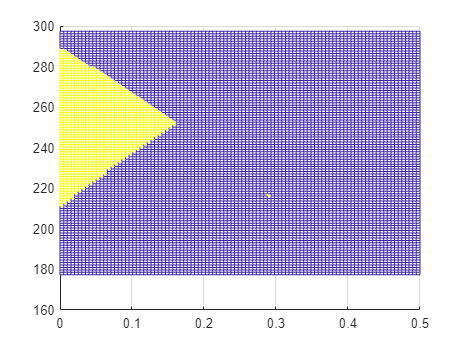

hold off
x = linspace(0,0.5,100);
y = linspace(l2,l1+l2,100);
[xM,yM] = ndgrid(x,y);

B1M = arrayfun(@(x,y) eval(subs(B1,[alpha1,h],[x,y])),xM,yM);
B3M = arrayfun(@(x,y) eval(subs(B3,[alpha1,h],[x,y])),xM,yM);
theta1M = arrayfun(@(x,y) eval(subs(theta1,[alpha1,h],[x,y])),xM,yM);
theta3M = arrayfun(@(x,y) eval(subs(theta3,[alpha1,h],[x,y])),xM,yM);
% overlapping region is within all constraints, thus being our workspace
w1 = (theta1M<=thetau) & (theta1M>=thetal) & (theta3M<=thetau) & (theta3M>=thetal) & (B3M<=1) & (B1M>=0);
w2 = (B3M<=1) & (B1M>=0);
% mesh(xM,yM,w1);
% mesh(xM,yM,w2);
mesh(xM,yM,w2 & w1);

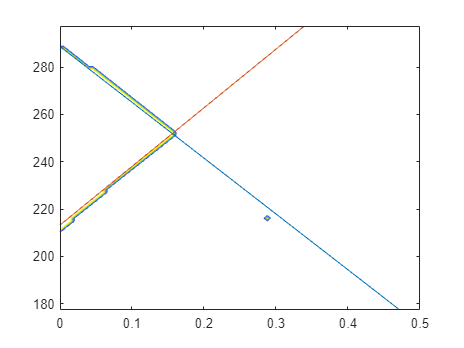

figure;
contour(xM,yM,w2 & w1);
hold on;
fplot(-225.01*alpha1+287);
fplot(247.778*alpha1+213.245);
xlim([0 0.5]); ylim([l2 l1+l2]);